
load class_data_test.mat
load class_data_train.mat
%loading in the new data
image_name_list=["dog.tif","dog2.tif","dog3.tif","cat.tif","cat1.tif","flower.tif","flower2.tif","bridge.tif","piano.tif","ukulele.tif","hot_chocolate.tif","icecream.tif","chair.tif", "chair2.tif","chair3.tif","face1.tif","face2.tif","face3.tif", "face4.tif", "face5.tif", "face6.tif","face7.tif"];
image_list=zeros(64*64,1,3);

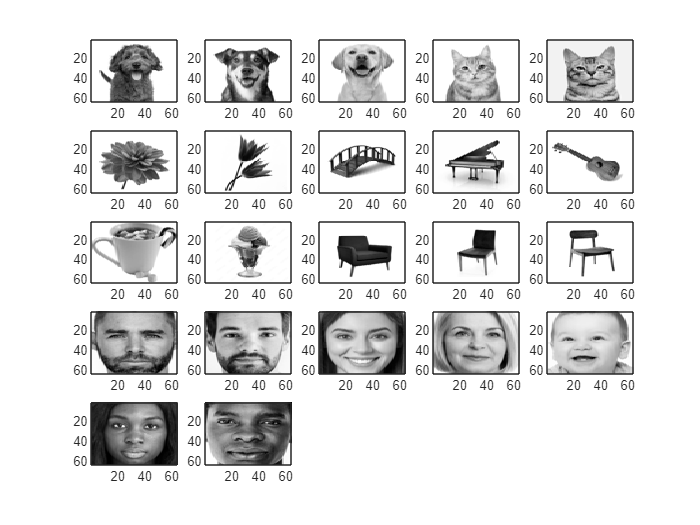


figure
for i=1:length(image_name_list)
    image=imread(image_name_list(i));
    resize_image=imresize(image(:,:,1:3),[64,64]);
    gray_image=rgb2gray(resize_image);
    subplot(5,5,i);
    imagesc(gray_image);
    colormap("gray")
    reshaped_image=reshape(gray_image,64*64,1);
    image_list(:,1,i)= reshaped_image(:,1);
end

clf


image_list;
number_of_PC=400

number_of_PC = 400

%centered_images=image_list-mean(image_list,2);%center the images
image_list2=reshape(image_list,[64*64,22]);%reshape the data
centered_images=image_list2-mean(image_list2,2);%center the images
grayfaces_train;%get the training images
grayfaces_test;%get the test images for training
A_train=reshape(grayfaces_train,[64*64,356]);%reshape the data
B_train=reshape(grayfaces_test,[64*64,356]);%reshape the data
A_train2=A_train-mean(A_train,2);%center data
B_train2=B_train-mean(B_train,2);%center the data
C=A_train2*A_train2';
[train_V_all,train_C_all]=eigs(C, 4096);%get all eigen vectors
[train_V,train_C]=eigs(C, number_of_PC);%get all eigen vectors
train_B_weights=train_V'*B_train2;%weights for B train
projection_train_B=train_V*train_B_weights;
test_image_weights=train_V'*centered_images;%weights for B train
projection_test_images=train_V*test_image_weights;


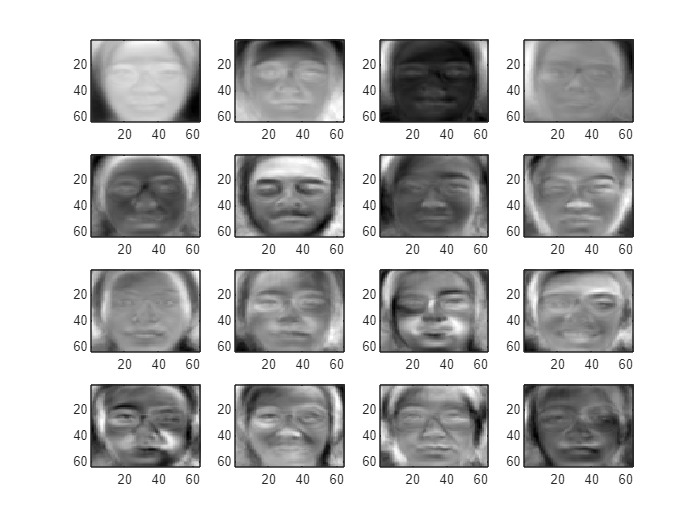

figure
for i=1:16%here are my eigien faces
    img_V=reshape(train_V(:,i),[64,64,1]);
    subplot(4,4,i);
    imagesc(img_V);
    colormap(gray);
end

clf


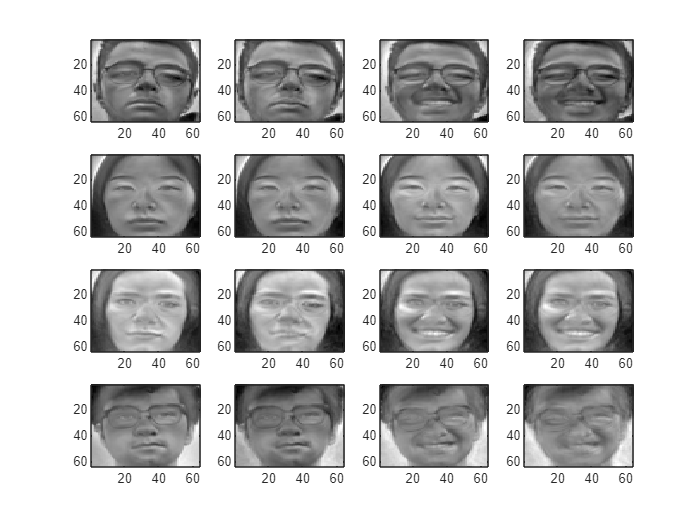


%projections of the train data B into the face space of train data a
figure
for i=1:16%here are my eigien faces
    img_V=reshape(projection_train_B(:,i),[64,64,1]);
    subplot(4,4,i);
    imagesc(img_V);
    colormap(gray);
end

clf

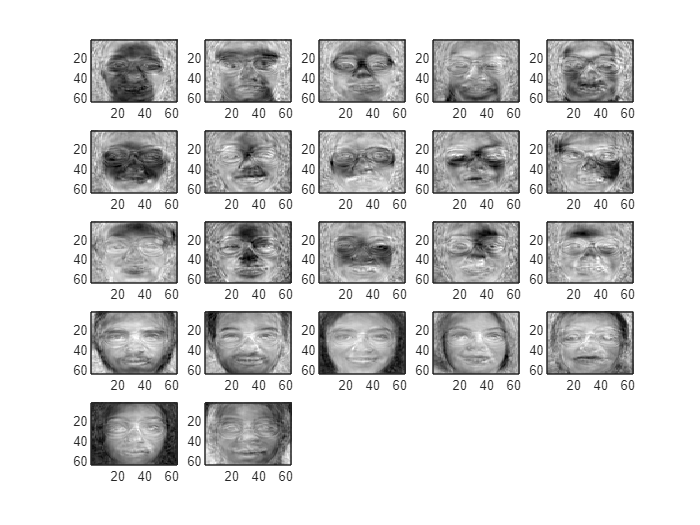

%projections of my test images into the face space
figure
for i=1:22%here are my eigien faces
    img_V=reshape(projection_test_images(:,i),[64,64,1]);
    subplot(5,5,i);
    imagesc(img_V);
    colormap(gray);
end

clf


trainB_all_weights=train_V_all'*B_train2;%get projetcion/ weights
test_image_all_weights=train_V_all'*centered_images; %get projection of the test images

trainB_distance_squared=sum((trainB_all_weights(number_of_PC:4096,:)).*(trainB_all_weights(number_of_PC:4096,:)));
trainB_distance=sqrt(trainB_distance_squared);
[maxdist, image_num]=max(trainB_distance);

test_distance_squared=sum((test_image_all_weights(number_of_PC:4096,:)).*(test_image_all_weights(number_of_PC:4096,:)));
test_distance=sqrt(test_distance_squared)

test_distance = 1.0e+03 *

    2.0656    2.4878    1.4924    1.1277    1.6258    1.6403    1.9459    2.5124    2.1325    1.9742    1.5232    1.5267    2.3079    1.8720    2.2901    1.2325    1.5125    1.1466    1.2163    1.3517    1.1756    1.5730


image_name_list

image_name_list = 1×22 string array
    "dog.tif"    "dog2.tif"    "dog3.tif"    "cat.tif"    "cat1.tif"    "flower.tif"    "flower2.tif"    "bridge.tif"    "piano.tif"    "ukulele.tif"    "hot_chocolate.tif"    "icecream.tif"    "chair.tif"    "chair2.tif"    "chair3.tif"    "face1.tif"    "face2.tif"    "face3.tif"    "face4.tif"    "face5.tif"    "face6.tif"    "face7.tif"


maxdist%from training

maxdist = 1.5336e+03

test_distance(16)

ans = 1.2325e+03

test_distance(17)

ans = 1.5125e+03

test_distance(22)

ans = 1.5730e+03

test_distance(11)

ans = 1.5232e+03

faces_detected=test_distance<=maxdist

faces_detected = 1×22 logical array
   0   0   1   1   0   0   0   0   0   0   1   1   0   0   0   1   1   1   1   1   1   0


image_name_list(faces_detected)

ans = 1×10 string array
    "dog3.tif"    "cat.tif"    "hot_chocolate.tif"    "icecream.tif"    "face1.tif"    "face2.tif"    "face3.tif"    "face4.tif"    "face5.tif"    "face6.tif"





%compute the distance for eachof the training images
% if the absolute value of the sum is less than or equal the
% A_test_distance then it is a face else it is not a face








%project it into the face space



%A_train2=A_train-mean(A_train,2)


%load second set of testing data with new faces and other objects
%subtract the mean to center it
%project it into the face space
%find the linear combination of all the smaller eigen vectors(all the ones we are not using) for the image
%find the absolute value of the sum
% if the absolute value of the sum is less than or equal the
% A_test_distance then it is a face else it is not a face







%load second set of testing data with new faces and other objects
%subtract the mean to center it
%project it into the face space
%find the linear combination of all the smaller eigen vectors(all the ones we are not using) for the image
%find the absolute value of the sum
% if the absolute value of the sum is less than or equal the
% A_test_distance then it is a face else it is not a face










%distance_facespace=abs(A_test_reshaped-test_weights(:,i_test))%distance between the origional image and the projected image
%check the distances. If the distances are large then it is not a face. if
%the distances are small then it is a face 

%if the distance is small aka it is a face then check then compare the
%projection to see how close it is to the other faces. If close to a face
%then it is that face. If not close to a face then it is not a face